# **Homework n°2 2023/2024**

### *Francesco Ferrillo 0124002921*

Imposto il formato `long` per la visualizzazione dei dati.

format long;

## *Punto 1:*

*"Definire un dominio *$[a,b]$* ed una funzione composta *$f(x)$* in MATLAB combinando  le principali funzioni elementari (polinomi, funzioni trigonometriche, logaritmi, esponenziali, etc.). Per stabilire un intervallo nel quale *$f$*sia definita e non prensenti punti di discontinuità, utilizzare eventualmente la function MATLAB ezplot per osservarne il grafico."*

*"Definire quindi un insieme di *$m$* punti *$P=\{(x_i,y_i)\}_{i=1}^m$* con *$8 \leq m \leq 19, m \in \mathbb{N}$*. Le ascisse di *$P$* sono linearmente distribuite in *$[a,b]$*, le ordinate sono i corrispondenti valori assunti dalla valutazione di *$f(x)$*."*

Definisco una funzione $f(x) = \log(2 + e^x  ) - 4  \cos(x)$ in un intervallo $[0, 16]$.

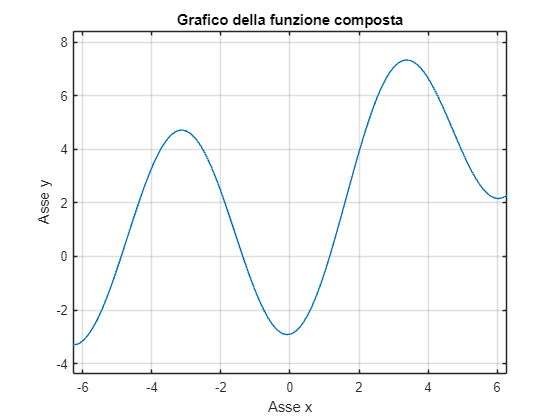

figure
% Definire la funzione composta
f = @(x) log( 2 + exp(x)) - 4 * cos(x);

% Visualizzare il grafico della funzione usando ezplot
ezplot(f);
grid on;
title('Grafico della funzione composta');
xlabel('Asse x');
ylabel('Asse y');

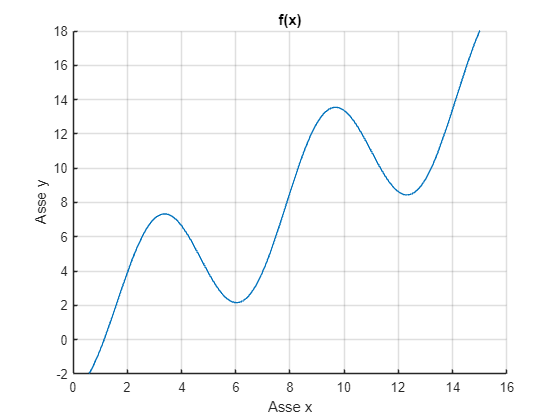

% Definire l'intervallo e generare i punti
a1 = 0;
b1 = 16;

% Visualizzare i punti (x, y)
figure
hold on
grid on
fplot(f, [a1, b1])
axis([a1 , b1 , -2, 18])
title('f(x)')
xlabel('Asse x');
ylabel('Asse y');
hold off

Definisco i nodi ed i valori:

m = 8; % Numero nodi
h = (b1 - a1) / (m - 1); % Passo di incremento
x = linspace(a1, b1, m)';
clear h % Cancello h

y = f(x); % Calcolo dei valori della funzione nei nodi

#### Punto 1.1:

*"Definire un insieme *$\mathcal{F}$*di funzioni modello polinomiali. Scegliere un'opportuna base così da determinare il polinomio *$p$  $\in$ $\mathcal{F}$* che interpola *$f$* nei nodi *$x_i$*. Costruire il relativo sistema lineare *$Ba=y$* e risolverlo (non usare il comando backslash di MATLAB).  Calcolare inoltre l'indice di condizionamento della matrice *$B$*."*

Come funzione di base utilizzo $x^{(n-1)}$. Faccio partire il `for` da 2, dato che se lo volessi far partire da 1 avrei delle operazioni inutili (pochè la prima colonna della *matrice di Vandermonde *è composta solo da $x^0$ e quindi da tutti 1).

b = @(x, n) x.^(n - 1);
B = ones(m,m); % Prealloco la matrice
for n = 2 : m
B(:, n) = b(x, n);
end
fprintf('Rango della matrice: %d\nDeterminante della matrice: %d', rank(B), det(B));

Rango della matrice: 8
Determinante della matrice: 1.415635e+21

Il rango della matrice è massimo ed il determinante è diverso da zero

Quindi la matrice è **non-singolare**.

a = SGauss(B, y);
cond(B) % Indice di condizionamento

ans =      3.508937474752269e+09


L'indice di condizionamento è elevato, il che è appropriato poiché il sistema di riferimento è un sistema lineare rappresentato da una matrice 8x8.

#### Punto 1.2:

*"*Valutare il polinomio $p$ su una griglia di $N$ punti di valutazione distribuiti casualmente in $[a,b]$. Fissare $N\,\,( 314 \leq N \leq 341)$. Calcolare l'errore di interpolazione della funzione interpolante scelta al punto precedente.*" *

Ho scelto 327 come numero di punti di valutazioni, costruiamo una griglia di punti di valutazione, poi generiamo una matrice di Vandermonde utilizzando le valutazioni della funzione b(x) sui punti di valutazione xx.

xx = a1 + (b1 - a1) * rand(327, 1); % Generazione di numeri casuali
xx = sort(xx); % Ordinamento del vettore
BB = ones(length(xx), m); % Inizializzazione della matrice
for j = 2 : m 
    BB(:, j) = b(xx, j);
end

Il ciclo for riempie la matrice "BB", per ogni colonnna da 2 a "m".

Calcoliamo i valori del polinomio interpolante sulla griglia $xx$ eseguendo il prodotto tra la matrice $BB $ e il vettore $a$, ovvero $BB \cdot a$.

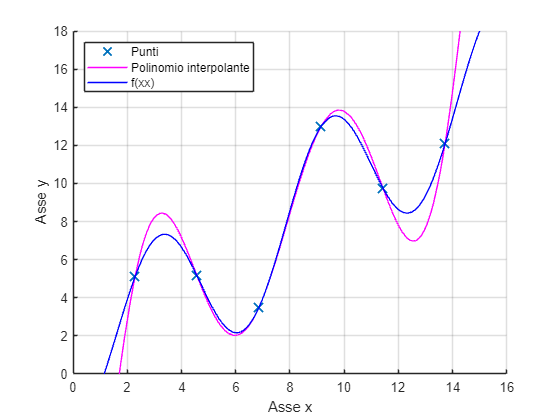

figure
hold on;
grid on;

% Calcolo del prodotto matrice-vettore
yy = BB * a;
plot(x, y, 'X', 'MarkerSize', 10,'LineWidth', 1.5);

% Impostazione degli assi
xlim([a1, b1]);
ylim([0, 18]);

% Tracciamento del polinomio interpolante e della funzione f(xx)
plot(xx, yy, 'm');
plot(xx, f(xx), 'b');

xlabel('Asse x');
ylabel('Asse y');

% Aggiunta della legenda
legend({'Punti', 'Polinomio interpolante', 'f(xx)'}, 'Location', 'northwest');

hold off;

errInt = abs(yy - f(xx))

errInt =    0.667969944298273
   2.065539104452593
   2.095049684121663
   2.508964898767826
   4.092455519365611
   4.298870325489616
   5.445530776550701
   5.612918051951159
   6.184030002134609
   6.232768900325961


Osserviamo che l'errore di interpolazione è complessivamente accettabile per le varie componenti, sebbene tenda ad aumentare vicino agli estremi.

#### Punto 1.3:

*"Interpolare i punti *$P$* mediante una spline *$s$* di terzo grado di tipo not-a-knot.  Valutare l'interpolante ottenuto sulla griglia di *$N$* punti di valutazione del punto 1.2*.*"*

Utilizzando la funzione spline, otteniamo una spline not-a-knot; mentre ppval ci permette di valutare un polinomio a tratti su un insieme di ascisse, che costituiscono la nostra griglia di valutazione.

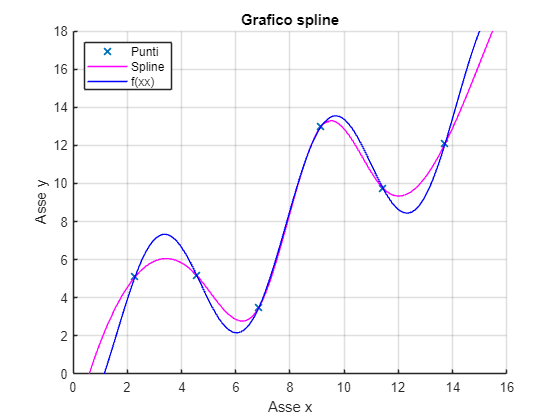

figure
hold on
grid on

pp = spline(x, y);
yy_spline = ppval(pp, xx);

plot(x, y, 'X', 'MarkerSize', 7,'LineWidth', 1.5)

xlim([a1, b1]);
ylim([0, 18]);

plot(xx, yy_spline, 'm', 'MarkerSize', 7)
plot(xx, f(xx), 'b', 'MarkerSize', 7)

xlabel('Asse x');
ylabel('Asse y');
title('Grafico spline')
legend('Punti', 'Spline', 'f(xx)','Location', 'northwest')
hold off

Come ci si poteva aspettare, la spline approssima meglio la nostra funzione di riferimento.

#### Punto 1.4:

*"Fissare un valore *$n\,\,( 7 \leq n \leq 17)$* e definire un nuovo insieme di punti *$Q = \{(x_j, y_j)\}_{j=1}^n$* le cui ascisse sono i nodi di Chebyshev in *$[a,b]$* e le cui ordinate sono i valori corrispondenti assunti da *$f(x)$*. Costruire il polinomio interpolante i punti *$Q$* e valutarlo sulla griglia di valutazione generata al punto 1.2."*

Ho scelto 7 come numero di punti, i nodi di Chebychev sono equispaziati. I nodi sono definiti come $x_k = cos\Big(\frac{k}{n-1}\pi\Big) \quad k=0,\ldots,n$, i nodi possono essere traslati.

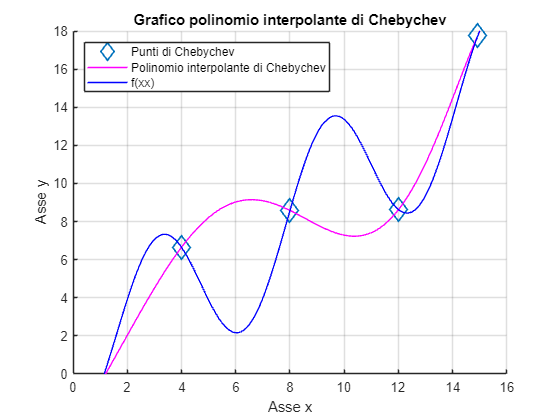

figure
hold on
grid on
nC = 7; % Numero di nodi di Chebychev
xc = -cos((0 : nC - 1) * pi/(nC - 1)); % Calcolo dei nodi di Chebychev nell'intervallo [-1, 1]
x_cheb = ((a1 + b1) / 2 + (b1 - a1) / 2 * xc)'; % Traslazione dei nodi di Chebychev nell'intervallo [a1, b1]
y_cheb = f(x_cheb); % Valutazione della funzione f nei nodi di Chebychev

% Creazione della matrice di Vandermonde per i nodi di Chebychev
B_cheb = ones(nC, nC);
for j = 1 : nC
    B_cheb(:, j) = b(x_cheb, j);
end

a_cheb = SGauss(B_cheb, y_cheb); % Calcolo dei coefficienti del polinomio interpolante usando la decomposizione di Gauss
 
% Creazione della matrice di Vandermonde per i punti di valutazione xx
BB_cheb = ones(327, nC);
for j = 1 : nC
    BB_cheb(:, j) = b(xx, j);
end

yy_cheb = BB_cheb * a_cheb;

plot(x_cheb, y_cheb, 'd', 'MarkerSize', 12,'LineWidth', 1.5) % Tracciamo i nodi di Chebychev con dimensione del marcatore 12
xlim([a1, b1]);
ylim([0, 18]);
plot(xx, yy_cheb, 'm', 'MarkerSize', 7)
plot(xx, f(xx), 'b', 'MarkerSize', 7)
xlabel('Asse x');
ylabel('Asse y');
title('Grafico polinomio interpolante di Chebychev')
legend('Punti di Chebychev', 'Polinomio interpolante di Chebychev', 'f(xx)','Location', 'northwest')
hold off

#### Punto 1.5:

*"Infine, mostrare graficamente l'andamento dell'errore di interpolazione. Confrontare numericamente l'errore con quello ottenuto al punto 1.2."*

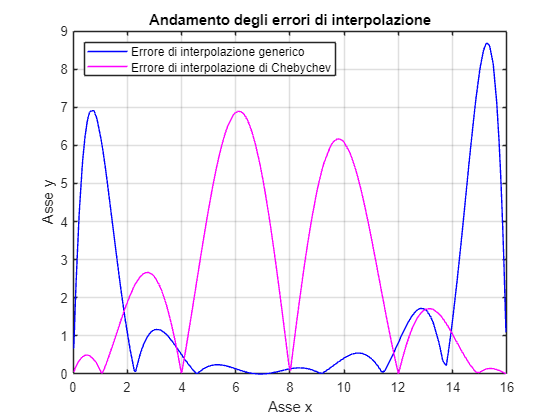

figure

% Tracciamo l'errore di interpolazione generico 
plot(xx, errInt, 'b', 'MarkerSize', 7)
hold on
grid on

% Calcolo dell'errore di interpolazione per i nodi di Chebychev
errIntC = abs(f(xx) - yy_cheb);

% Tracciamo l'errore di interpolazione per i nodi di Chebychev in rosso
plot(xx, errIntC, 'm', 'MarkerSize', 7)

xlabel('Asse x');
ylabel('Asse y');
title('Andamento degli errori di interpolazione')
legend('Errore di interpolazione generico', 'Errore di interpolazione di Chebychev','Location', 'northwest')
hold off

errIntC < errInt

ans = 327×1 logical array
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


## Punto 2:

*" Si considerino le seguenti curve parametriche:*

*         1. *$\begin{cases}
x = \frac{a \cdot \cos(\theta)}{1 + \sin^2(\theta)} \\
y = \frac{a \cdot \sin(\theta) \cdot \cos(\theta)}{1 + \sin^2(\theta)}
\end{cases}
\quad 0 \leq \theta \leq 2\pi$

*         2. *$\begin{cases}
x = \sin(\theta) \left(e^{\cos(\theta)} - 2 \cos(4\theta) - \sin^5\left(\frac{\theta}{12}\right)\right) \\
y = \cos(\theta) \left(e^{\cos(\theta)} - 2 \cos(4\theta) - \sin^5\left(\frac{\theta}{12}\right)\right)
\end{cases}
\quad 0 \leq \theta \leq 12\pi$

*         3. *$\begin{cases}
x = a \cdot \theta \cdot \cos(\theta) \\
y = a \cdot \theta \cdot \sin(\theta)
\end{cases}
\quad 0 \leq \theta \leq 4\pi$

*Scegliere una di tali curve e campionarla in *$n$* punti *$P=\{(x_i,y_i)\}_{i=1}^n$*, corrispondenti a *$n$* punti *$t_i$* equispaziati nell'intervallo *$[a,b]$* in cui varia il parametro *$t$* (fissare *$20<n<30$*).* *"*

% Parametri iniziali
aa = 1; 
n2 = 25; % Numero di punti di campionamento (20 < n < 30)
theta_min = 0;
theta_max = 2 * pi;

% Campionamento equidistante di theta
theta = linspace(theta_min, theta_max, n2);

% Calcolo delle coordinate x e y per la curva 1
x = aa .* cos(theta) ./ (1 + sin(theta).^2);
y = aa .* sin(theta) .* cos(theta) ./ (1 + sin(theta).^2);

#### Punto 2.1:

*"Costruire due spline parametriche *$p_x$* e *$p_y$* che interpolino rispettivamente i punti *$(t_i,x_i)$* e i punti *$(t_i, y_i)$*  (*$i = 1,\ldots, n$*);"*

px = spline(theta, x);
py = spline(theta, y);

#### Punto 2.2:

*"Valutare le spline parametriche su una griglia fitta *$\Gamma$* opportuna e mostrare il grafico della curva parametrica interpolata."*

theta_fine = linspace(theta_min, theta_max, 100);
x_fine = ppval(px, theta_fine);
y_fine = ppval(py, theta_fine);

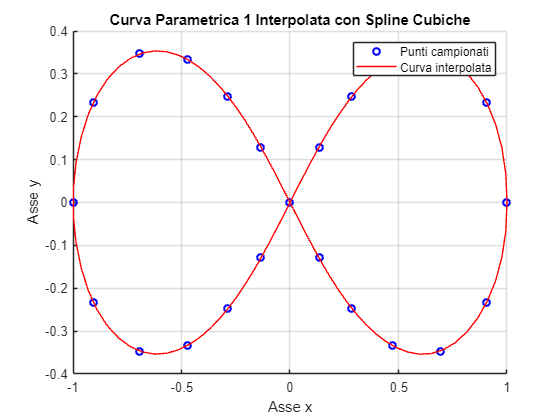

figure
hold on;
grid on;

plot(x, y, 'bo', 'MarkerSize', 5, 'LineWidth', 1.5); % Punti campionati
plot(x_fine, y_fine, 'r-'); % Curva interpolata
title('Curva Parametrica 1 Interpolata con Spline Cubiche');

xlabel('Asse x');
ylabel('Asse y');
legend('Punti campionati', 'Curva interpolata');
hold off;

#### Punto 2.3:

*"Ripetere i punti 2.1 e 2.2 su un insieme di *$m=50$* punti *$S = \{(x_j,y_j)\}_{j=1}^m$* le cui ascisse ed ordinate sono valori ottenuti dall'utilizzo del comando *`ginput`* usato su una immagine a propria scelta oppurtunamente caricata (usare *`imread).                                          `*Le coordinate devono essere estese aggiungendo in coda un punto fittizio coincidente col primo punto, in modo tale che *`x`* e *`y`* siano i vettori delle coordinate dei vertici di un poligono (chiuso). "*

figure
ascia = imread("ascia.jpg");

Carico l'immagine "ascia.jpg", Utilizzo la funzione `ginput` per prendere manualmente 50 punti, poi salvo i dati con `save,` e infine li carico con `load,` ho commentato queste righe per evitare di ripetere i punti nelle esecuzioni successive.

%imshow(ascia)
%[asciaX, asciaY] = ginput(50)
%save('DatiHW.mat', 'asciaX', 'asciaY');
load("DatiHW2.mat")

Adesso creo nodi finti per chiudere la figura.

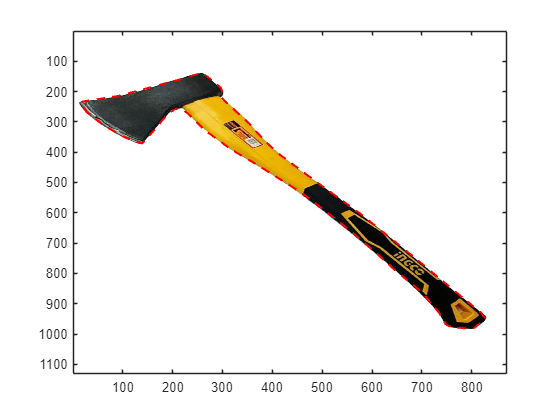

asciaX(end + 1) = asciaX(1);
asciaY(end + 1) = asciaY(1);
image(ascia)
hold on
plot(asciaX, asciaY, '--r', 'LineWidth', 1.5);
hold off

Creo due spline, una sull'asse `x` e una sull'asse `y`, per rappresentare la curva parametrica in funzione della variabile temporale `t`.

`ttascia` è un vettore che contiene 300 valori equidistanti tra il primo e l'ultimo indice temporale presente in `tascia,` questo vettore viene utilizzato per determinare i punti in cui si desidera valutare la spline cubica interpolata.

tascia = 1 : length(asciaX);
ttascia = linspace(tascia(1), tascia(end), 300);

Il seguente codice effettua una trasformazione dei dati `asciaX` e `asciaY` per centrarli rispetto alla loro media, quindi utilizza una spline cubica per interpolare le curve parametriche in funzione del tempo. Questo processo è utile per ottenere una rappresentazione continua e liscia delle curve rispetto alla variabile di tempo `tascia`.

asciaX_centrato = mean(asciaX); % Calcola la media dei valori presenti in asciaX.
asciaY_centrato = mean(asciaY); % Calcola la media dei valori presenti in asciaY.
asciaX = asciaX - asciaX_centrato;
asciaY = - asciaY + asciaY_centrato;
asciaX_spline = spline(tascia, asciaX, ttascia); % Contiene i valori interpolati della curva asciaX 
asciaY_spline = spline(tascia, asciaY, ttascia); % Contiene i valori interpolati della curva asciaY 

Rappresentazione Grafica

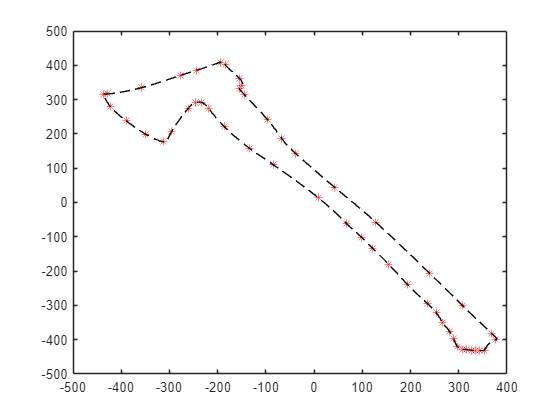

figure
plot(asciaX, asciaY, 'r*', asciaX_spline, asciaY_spline, '--k')

#### Punto 2.4:

*"Ricostruire inoltre la curva parametrica passante per i punti definiti al punto 2.3 mediante le cubiche di Hermite (non spline cubiche). Calcolare la norma infinito del vettore contenente le ordinate assunte dalla valutazione della cubica di Hermite su *$\Gamma$*."*

xxc = pchip(tascia, asciaX, ttascia);
yyc = pchip(tascia, asciaY, ttascia);

Rappresentazione Grafica

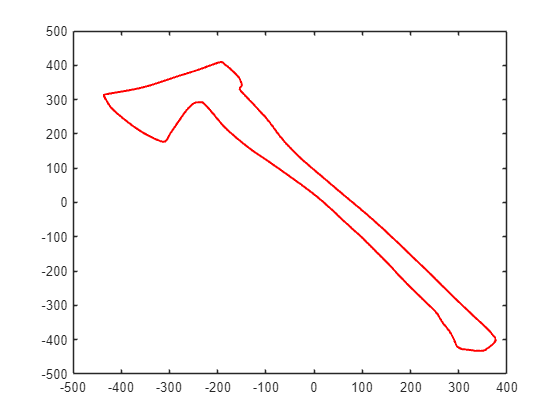

figure
plot(xxc, yyc, 'r', 'LineWidth', 1.5)

Come possiamo vedere l'ascia viene ricostruita perfettamente.

fprintf('Norma infinito del vettore: %d', norm(yyc, inf));

Norma infinito del vettore: 4.320000e+02

## Punto 3:

*"Generare un insieme di punti *$C=\{(t_i,y_i)\}_{i=1}^n$* le cui ascisse *$t_1,t_2,\ldots,t_n$* appartengono all'intervallo [3,4] e i valori  *$y_i$*  sono i valori perturbati della funzione *$f(t)=t^3-2t+17$* nei punti *$t_i$*, dove la perturbazione si intende introdotta aggiungendo un errore casuale tra 0 e 1 ad ogni valore *$y_i$*. Scegliere inoltre *$11 \leq n \leq 17$*."*

Come $n$ scelgo $14$.

nD = 14;
fx = @(t) t.^3 - 2*t + 17;
ct = (1 : nD)';
cy = zeros(nD, 1);
for j = 1 : nD
    cy(j) = fx(j);
end

#### Punto 3.1:

*"Costruire e valutare, su una griglia fitta di almeno 73 punti, utilizzando i metodi studiati, la cubica dei minimi quadrati approssimante i dati."*

Creo una griglia di 195 punti, poi costruisco la matrice come nei precedenti punti e utilizzo la formula $B^T B = B^T y$ per ottenere i coefficienti.

xxD= linspace(1, nD, 195);
BDa = [ct, ones(size(ct))];
aD = SGauss((BDa' * BDa), (BDa' * cy));
rettaMQ = polyval(aD, xxD);

#### Punto 3.2:

*"Mostrare graficamente sia il polinomio di terzo grado approssimante che i punti approssimati ed evidenziare sul grafico gli scostamenti."*

Uno *scostamento *è la differenza tra la $y$ e la sua proiezione sulla retta dei minimi quadrati.

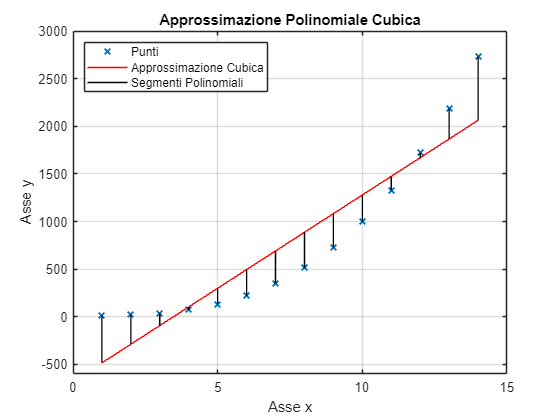

figure
plot(ct, cy, 'X', 'LineWidth', 1.5)
hold on
grid on
plot(xxD, rettaMQ, 'r')
for i = 1 : nD 
    plot([ct(i), ct(i)], [polyval(aD, ct(i)), cy(i)], 'k')
end

xlabel('Asse x');
ylabel('Asse y');
title('Approssimazione Polinomiale Cubica');

legend('Punti', 'Approssimazione Cubica', 'Segmenti Polinomiali', 'Location', 'northwest');
axis([ct(1) - 1, nD + 1, -600, 3000])

hold off

#### Punto 3.3:

*"Ripetere il punto precedente variando il grado del polinomio approssimante nell'intervallo tra 1 e 5. Mostrare tutte le curve approssimanti ottenute sullo stesso grafico."*

Effettuo la variazione del polinomio approssinamente nell'intervallo tra $[1, 5]$, per poi visualizzare i vari polinomi con grado tra 1 e 5.

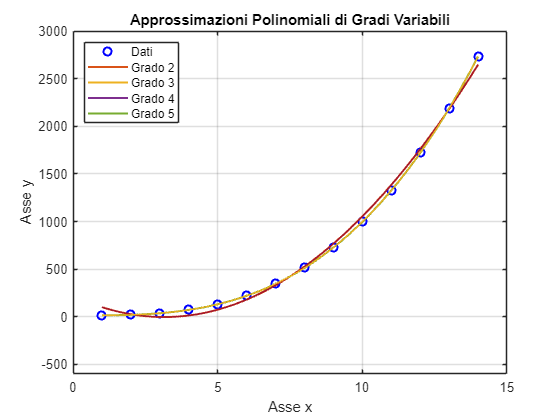

polinomi = zeros(length(xxD), 4);
for i = 1 : 4
    polinomi(:, i) = polyval(polyfit(ct, cy, i + 1), xxD)';
end

figure
plot(ct, cy, 'bo', xxD, polinomi, 'LineWidth', 1.5)
hold on
grid on

legenda_nomi = cell(1, 5);  
legenda_nomi{1} = 'Dati';  
for i = 1 : 4
    legenda_nomi{i+1} = ['Grado ', num2str(i + 1)]; 
end

plot(ct, cy, 'bo', xxD, polinomi)
xlabel('Asse x');
ylabel('Asse y');
title('Approssimazioni Polinomiali di Gradi Variabili');
legend(legenda_nomi, 'Location', 'northwest');
axis([ct(1) - 1, nD + 1, -600, 3000])

hold off

#### Punto 3.4:

*"Valutare il residuo in norma due per ognuna delle curve precedentemente ottenute."*

residuiMinimiQuadrati = zeros(nD, 4);
for i=1:4
    %calcolo dei residui dei polinomi MQ di grado 1:5
    residuiMinimiQuadrati(:,i) = norm(abs(polyval(polyfit(ct, cy, i + 1), ct) - cy)', 2);
end
disp(residuiMinimiQuadrati)

   1.0e+02 *

   1.870999732763207   0.000000000000010   0.000000000000008   0.000000000000013
   1.870999732763207   0.000000000000010   0.000000000000008   0.000000000000013
   1.870999732763207   0.000000000000010   0.000000000000008   0.000000000000013
   1.870999732763207   0.000000000000010   0.000000000000008   0.000000000000013
   1.870999732763207   0.000000000000010   0.000000000000008   0.000000000000013
   1.870999732763207   0.000000000000010   0.000000000000008   0.000000000000013
   1.870999732763207   0.000000000000010   0.000000000000008   0.000000000000013
   1.870999732763207   0.000000000000010   0.000000000000008   0.000000000000013
   1.870999732763207   0.000000000000010   0.000000000000008   0.000000000000013
   1.870999732763207   0.000000000000010   0.000000000000008   0.000000000000013
   1.870999732763207   0.000000000000010   0.000000000000008   0.000000000000013
   1.870999732763207   0.000000000000010   0.000000000000008   0.000000000000013
   1.870999732

## Punto 4:

#### Punto 4.1:

*"Definire un dominio *$[a,b]$* ed una funzione composta *$f(x)$* in MATLAB combinando  le principali funzioni elementari. Assicurarsi che la funzione scelta sia positiva e continua nell'intervallo fissato *$[a,b]$*"*

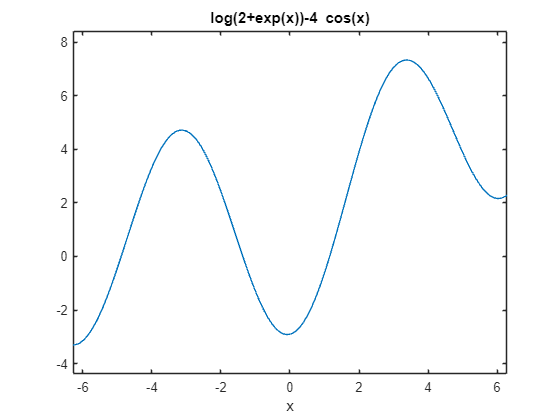

% Definire il dominio [a, b]
a1Q = 0;
b1Q = 4;
fQuad = @(x) log( 2 + exp(x)) - 4 * cos(x); % Definire una funzione composta f(x)
ezplot(fQuad)

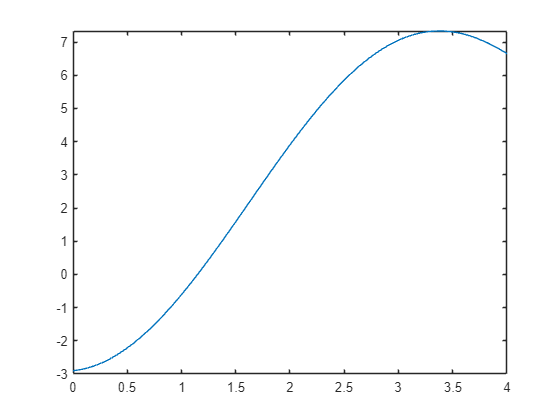

figure
fplot(fQuad, [a1Q, b1Q])

#### Punto 4.2:

*"Considerare *$I=I[f]=\int_a^b f(x)dx$* il valore ottenuto mediante la funzione MATLAB  integral con *$tol=10^-9$* "*

integrale = integral(fQuad, a1Q, b1Q, 'AbsTol', 1e-9)

integrale =   12.427655181405992


#### Punto 4.3:

*"Stimare l'integrale *$I$* utilizzando le formule di quadratura composite su m sottointervalli, relative ad un delle due seguenti  formule base: Trapezoidale e Simpson, con m che varia tra le seguenti 5 potenze di: 2,4,8,16, 32. Per ognuna di esse calcolare il corrispondente errore di discretizzazione."*

Formula del **punto medio, rettangolare sinistra **e **rettangolare destra **su **1 nodo**.

IRSx = (b1Q - a1Q) * fQuad(a1Q)

IRSx =  -11.605550845327562


IRDx = (b1Q - a1Q) * fQuad(b1Q)

IRDx =   26.602203132810565


IPMedio = (b1Q - a1Q) * fQuad((a1Q + b1Q) / 2)

IPMedio =   15.616528449641816


% Array di suddivisioni
m_values = [2, 4, 8, 16, 32];

% Loop sulle diverse suddivisioni
for m = m_values
    % Suddivisione dell'intervallo
    h = (b1Q - a1Q) / m;
    x = linspace(a1Q, b1Q, m+1);

    % Formula trapezoidale 
    ITrapez = 0;
    for i = 1:m
        ITrapez = ITrapez + (x(i+1) - x(i)) / 2 * (fQuad(x(i)) + fQuad(x(i+1)));
    end

     % Formula di Simpson
    ISimpson = 0;
    for i = 1:2:m-1
        ISimpson = ISimpson + (x(i+2) - x(i)) / 6 * (fQuad(x(i)) + 4 * fQuad((x(i) + x(i+2)) / 2) + fQuad(x(i+2)));
    end
    
    % Visualizzazione dei risultati
    fprintf('m = %d:    Trapezio = %.8f,    Simpson = %.8f\n', m, ITrapez, ISimpson);
end

m = 2:    Trapezio = 11.55742730,    Simpson = 12.91046101
m = 4:    Trapezio = 12.22384208,    Simpson = 12.44598034
m = 8:    Trapezio = 12.37748589,    Simpson = 12.42870050
m = 16:    Trapezio = 12.41516077,    Simpson = 12.42771906
m = 32:    Trapezio = 12.42453455,    Simpson = 12.42765915


Calcolo l'errore di discretizzazione:

errRectSx = abs(IRSx - integrale)

errRectSx =   24.033206026733552


errRectDx = abs(IRDx - integrale)

errRectDx =   14.174547951404573


errPMedio = abs(IPMedio - integrale)

errPMedio =    3.188873268235824


errTrapez = abs(ITrapez - integrale)

errTrapez =    0.003120626611841


errSimpson = abs(ISimpson - integrale)

errSimpson =      3.969863703545684e-06


table(errRectSx,errRectDx,errPMedio,errTrapez,errSimpson)

ans = 1×5 table
       errRectSx           errRectDx           errPMedio             errTrapez              errSimpson     
    ________________    ________________    ________________    ___________________    ____________________

    24.0332060267336    14.1745479514046    3.18887326823582    0.00312062661184065    3.96986370354568e-06


#### Punto 4.4:

*"****Costruzione di formule di quadratura. ****Fissare 4 nodi distinti ****non*** ***equispaziati****, *$x_i \in [1,5]$*  di una formula di quadratura *$Q[f]=w_1f(x_1)+w_2f(x_2)+w_3f(x_3)+w_4f(x_4)$ *per il calcolo numerico dell'integrale definito della funzione *$f$* in *$[0,4]$*;"*

% Definire i nodi non equispaziati nell'intervallo [1, 5]
x1 = 1;
x2 = 2;
x3 = 3;
x4 = 5;

xQuad = (x4 - x1) * rand(x4, 1) + x1;
xQuad = sort(xQuad);
I = ones(4, 1);
for i = 1 : x4
    I(i, 1) = ((xQuad(end)^i - xQuad(1)^i) / i);
end

#### Punto 4.5:

*"Determinare i valori dei pesi *$w_i$* affinché la formula risulti esatta per polinomi algebrici di grado al più 3 (costruire e risolvere il sistema *$B^Tw=I$*)."*

BQ = [ones(size(xQuad)), xQuad, xQuad.^2, xQuad.^3]'

BQ = 1.0e+02 *

   0.010000000000000   0.010000000000000   0.010000000000000   0.010000000000000   0.010000000000000
   0.012913232192497   0.021128441610526   0.022899263522478   0.040048944234880   0.049045861409094
   0.016675156565734   0.044641104488940   0.052437626987190   0.160391793432855   0.240549652136008
   0.021533016857957   0.094319696962394   0.120078303887307   0.642352199092487   1.179796490066847


w = SGauss(BQ, I);
Quadratura = sum(w(1 : 5) .* fQuad(xQuad(1 : 5)))

Quadratura =   18.566929079829450
